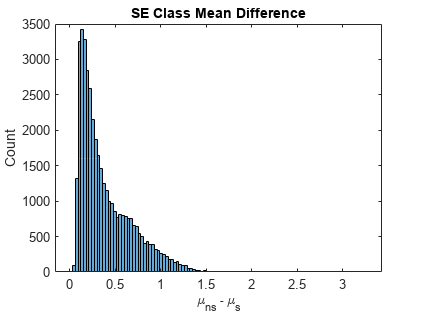

load store\POI.mat
poi = POI.DiscardPOIData(poi, 70, true);

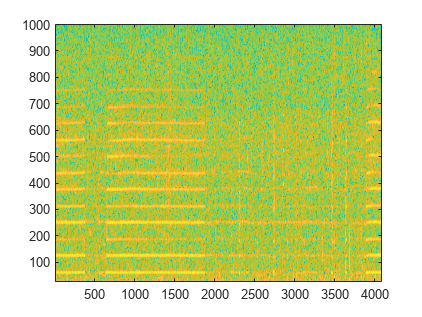

nint = [9864]; %fish
n = 9865;
f1 = POI.f1;
f2 = POI.f2;
fs = POI.fs;
ds = POI.getDataset(convertStringsToChars(poi(n).File));
Nfft = POI.Nfft;
Noverlap = Nfft * POI.OverlapFactor;
k1 = POI.k1;
k2 = POI.k2;
s = poi(n).StartIndex;
fname = poi(n).File;
SEmask = poi(n).SignalProbability > 0.5;

x = POI.loadPOI(poi(n));

[S, f]= POI.PowerSpectrum(x);

S = S(k1:k2, :);
f = f(k1:k2);

Nmin = POI.Nmin;
Nmax = size(S, 2);
Smed = poi(n).MedianSpectrum;
Smedsmooth = smoothdata(Smed, "gaussian", 21);
Smed = Smed(k1:k2, :);
Smedsmooth = Smedsmooth(k1:k2, :);
St = S.*SEmask >= Smed*POI.MFThresh;

Sden = max(S - Smedsmooth, 1e-12);

CC = bwconncomp(St, 8);

Cdata = POI.ProcessContours(CC, Sden, St, f);

hrtol = 0.05;
ratios = (1:20)./(1:20)';
temp(1,:) = ratios(ratios > 1);
ratios = temp;
ratiosTolUp = ratios*(1+hrtol);
ratiosTolDown = ratios/(1+hrtol);

%                 figure
%                 hold on
%                 Tools.plotTF(S, f, false, true);
%                 for i = 1:numel(Cdata)
%                     c = Cdata{i};
%                     plot(c.tmin:c.tmax, c.f0, 'k');
%                 end
%                 hold off

remove = zeros(1, numel(Cdata)) == 1;
for i = 1:numel(Cdata)
    c = Cdata{i};
    dur = c.tmax - c.tmin + 1;
    if dur <= Nmin || dur >= Nmax
        remove(i) = true;
        %                         St(c.idx) = false;
    end
end
Cdata = cell2mat(Cdata);
Cdata = Cdata(~remove);

remove = zeros(1, numel(Cdata)) == 1;
for i = 1:numel(Cdata)
    ci = Cdata(i);
    if ~remove(i)
        for j = 1:numel(Cdata)
            cj = Cdata(j);
            if i ~= j && ~remove(j)
                sameTime = ci.tmin <= cj.tmax & ci.tmax >= cj.tmin;
                if sameTime
                    cijtmin = min(ci.tmin, cj.tmin);
                    cijtmax = max(ci.tmax, cj.tmax);
                    ovl = min(ci.tmax, cj.tmax) - max(ci.tmin, cj.tmin);
                    f0i = NaN(cijtmax - cijtmin + 1, 1);
                    f0j = f0i;
                    f0i((ci.tmin:ci.tmax) - cijtmin + 1) = ci.f0;
                    f0j((cj.tmin:cj.tmax) - cijtmin + 1) = cj.f0;
                    hratio = f0j./f0i;
                    f0 = f0j ./ ratios;
                    withinTol = any((hratio <= ratiosTolUp & hratio >= ratiosTolDown) & f0 > 8*fs/Nfft, 2);
                    withinTol = sum(withinTol) >= ceil(ovl*POI.PHarmonic);
                    if withinTol
                        remove(j) = true;
                        %                                         St(cj.idx) = false;
                    end
                end
            end
        end
    end
end

%                 figure
%                 Tools.plotTF(St, f, false, false);

regs = {};


Cdata = Cdata(~remove);
for i = 1:numel(Cdata)
    c = Cdata(i);

    %Bandwidth
    BW = POI.timeRangeFeats(c.bw);
    %Delta Bandwidth
    dBW = POI.timeRangeFeats(diff(c.bw));
    %Freq
    F0 = POI.timeRangeFeats(c.f0);
    %DeltaFreq
    dF0 = POI.timeRangeFeats(diff(c.f0));
    %Power of Contour
    P = POI.timeRangeFeats(c.P);
    %DeltaPower of Contour
    dP = POI.timeRangeFeats(diff(c.P));
    %TotalPower
    kbot = max(floor((F0(6)/2)/fs*Nfft) - k1,1); %only consider above F0min/2
    mask = ~St(:,c.tmin:c.tmax);
    Sm = Sden(:,c.tmin:c.tmax);
    Sm(mask) = 0;
    tp = sum(Sm(kbot:end, :), 1);
    TotP = POI.timeRangeFeats(tp);
    dTotP = POI.timeRangeFeats(diff(tp));
    %PowerRatio
    pr = c.P ./ tp;
    PRatio = POI.timeRangeFeats(pr);
    dPRatio = POI.timeRangeFeats(diff(pr));

    Tmin = c.tmin*(Nfft - Noverlap);
    Tdur = (c.tmax - c.tmin)*(Nfft - Noverlap);

    Sc = Sden(:, c.tmin:c.tmax);
    Sc = mean(Sc, 2);
    Sc = POI.MFCCFilterBank(:, k1:k2)*Sc;
    
    regs{i} = struct('Duration', Tdur/fs,...
        'FreqFeat', Sc', ...
        'Bandwidth', BW, 'DeltaBandwidth', dBW, 'Freq', F0, ...
        'DeltaFreq', dF0, 'Power', P, 'DeltaPower', dP, ...
        'TotPower', TotP, 'DeltaTotPower', dTotP,...
        'PowerRatio', PRatio, 'DeltaPowerRatio', dPRatio, ...
        'File', fname, 'Start', s + Tmin, 'End', s + Tmin + Tdur, 'Dataset', ds);
end

if numel(regs) ~= 0
    regs = cell2mat(regs);
    feats{n} = regs;
else
    feats{n} = NaN;
    nan_feats(n) = false;
end
figure
Tools.plotTF(S, f, false, true);

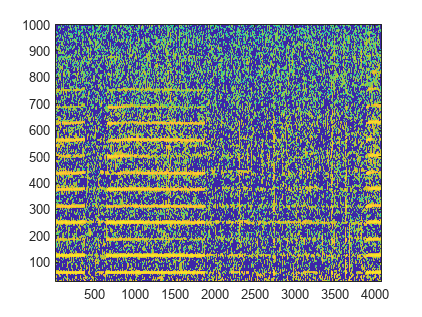


figure
Tools.plotTF(Sden, f, false, true);

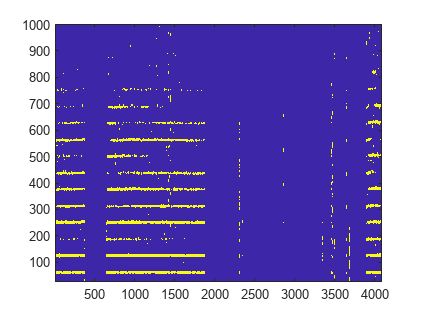

figure
Tools.plotTF(St, f, false, false);

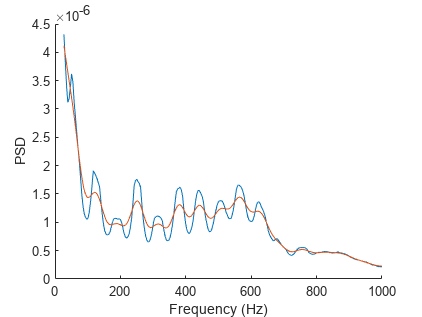



figure
hold on
Tools.plotPS(Smed, f);
Tools.plotPS(Smedsmooth, f);
hold off

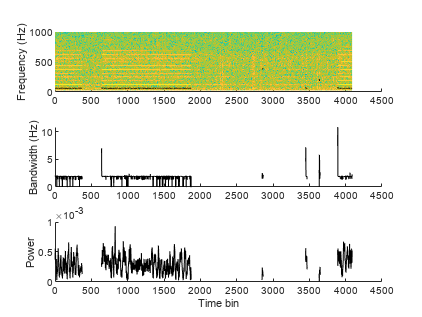

figure
Tools.plotContours(S, f, Cdata);

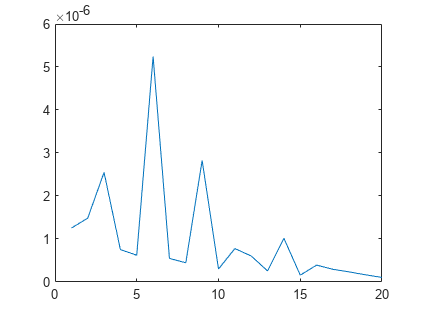

con = 5;
figure
plot(regs(con).FreqFeat)